# Gene expression part 04

## © 2017 Griffin Chure & Manuel Razo. This work is licensed under a [Creative Commons Attribution License CC-BY 4.0](https://creativecommons.org/licenses/by/4.0/). All code contained herein is licensed under an [MIT license](https://opensource.org/licenses/MIT)

We have gotten very far with this analysis! Now we are in position to extract the quantitative fluorescence information from our YFP reporter images. What that means is that since we can generate the segmentation mask using our fancy function, we can use this mask to extract the fluorescence value of each of the single cells and plot the fluorescence distribution.

The first thing I will do is modify our `segmenter` function in order to include the area filter that we developed in the previous tutorial

`generating segmenterAreaFilt function...`

Having defined that function let's again read our example image and generate the filtered segmentation mask.

% Define variable that points to the directory where the data is
dataDir = 'data/lacI_titration/delta/';
% List all the images that have the pattern 'nd2' on the file name
deltaIms = dir([dataDir, '*nd2']);

% Define the area bounds
areaBounds = [2, 3]; %µm^2
% Define the inter-pixel distance
interPix = 0.0733; %µm / pixel

% Generate segmentation mask
[imLabel, areas, imYFP] = segmenterAreaFilt([dataDir, deltaIms(1).name], 70,...
                                      areaBounds, interPix);

Reading series #1
    ...


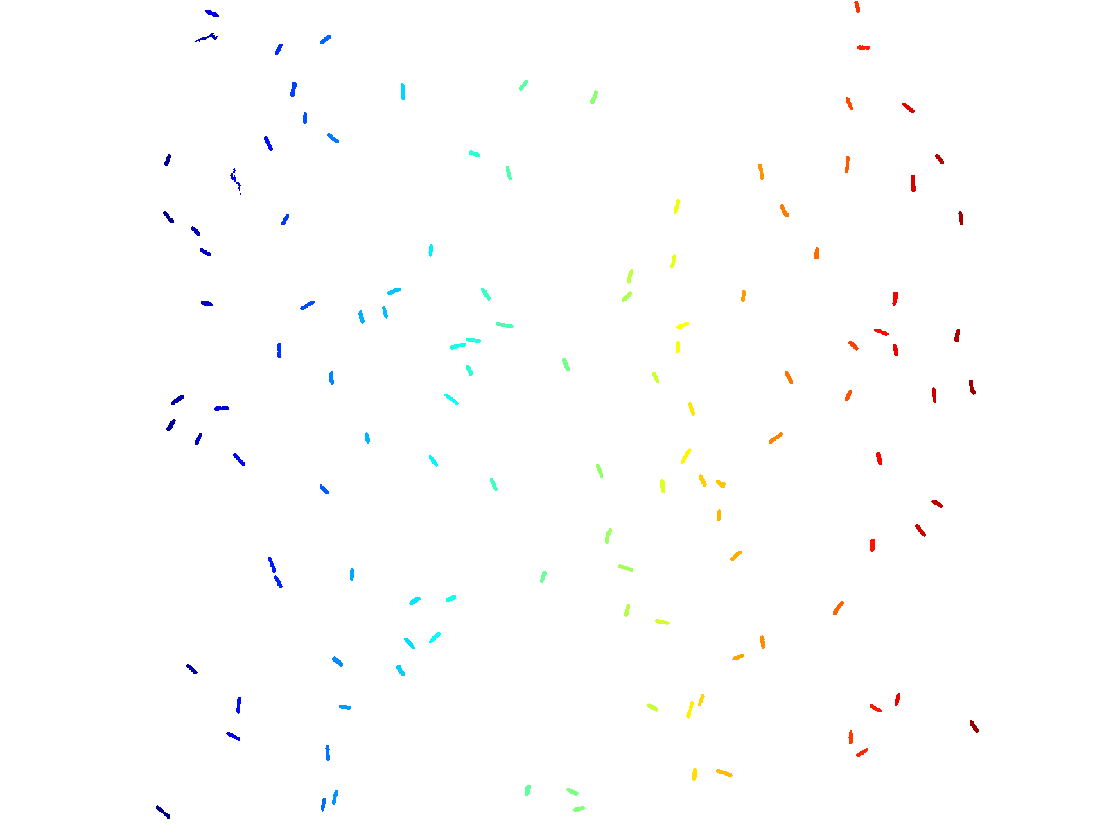

% display segmentation mask
imshow(label2rgb(imLabel));

Beautiful! Now in a single step we obtain a segmentation mask. Now we will loop through each of the labeled objects and interrogate each of the pixels withing the object for their YFP fluorescence value. 

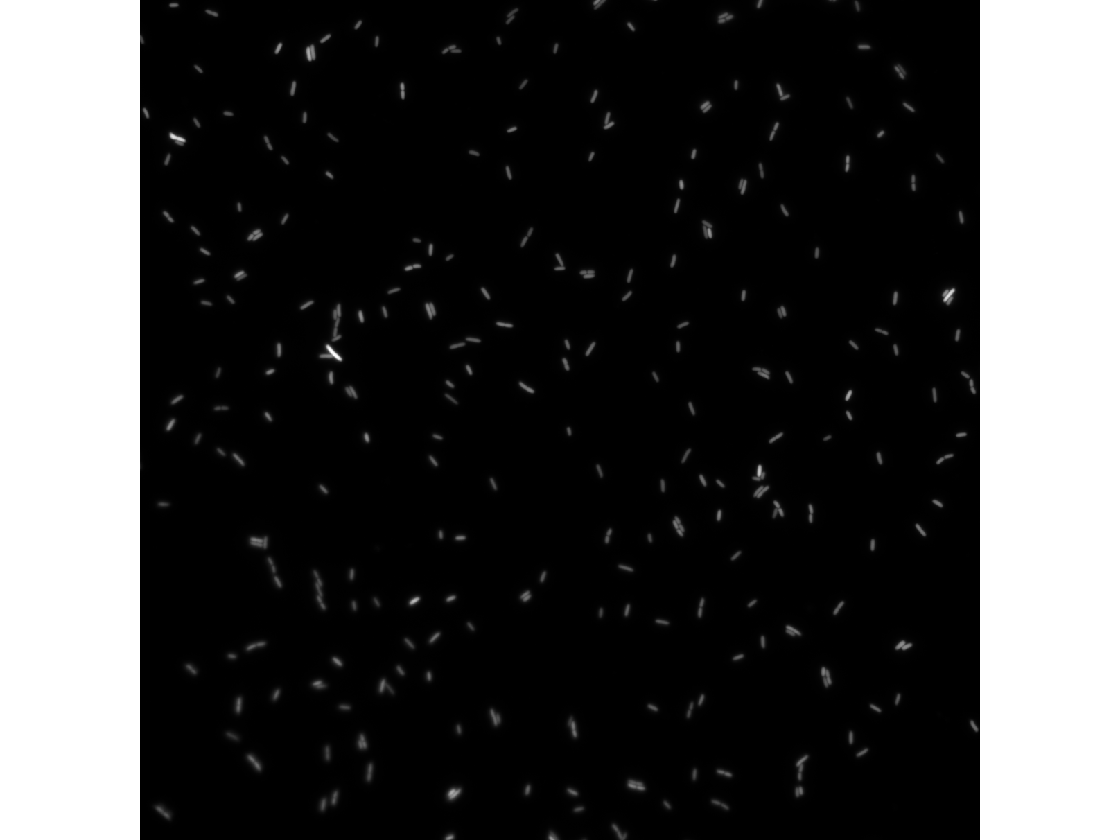

% display YFP channel
imshow(imYFP, [])

Now remember that if I ask matlab for `imLabel == 23` it will return a binary file where all the pixels within the object with the label `23` will take the value of 1 and the rest will be zero. Then if I were to multiply this binary image by `imYFP` we would get all of the pixel values inside this object. This is exactly the strategy that we will follow using a `for` loop to iterate through each of the labeled objects.

Let's first do it for a single object

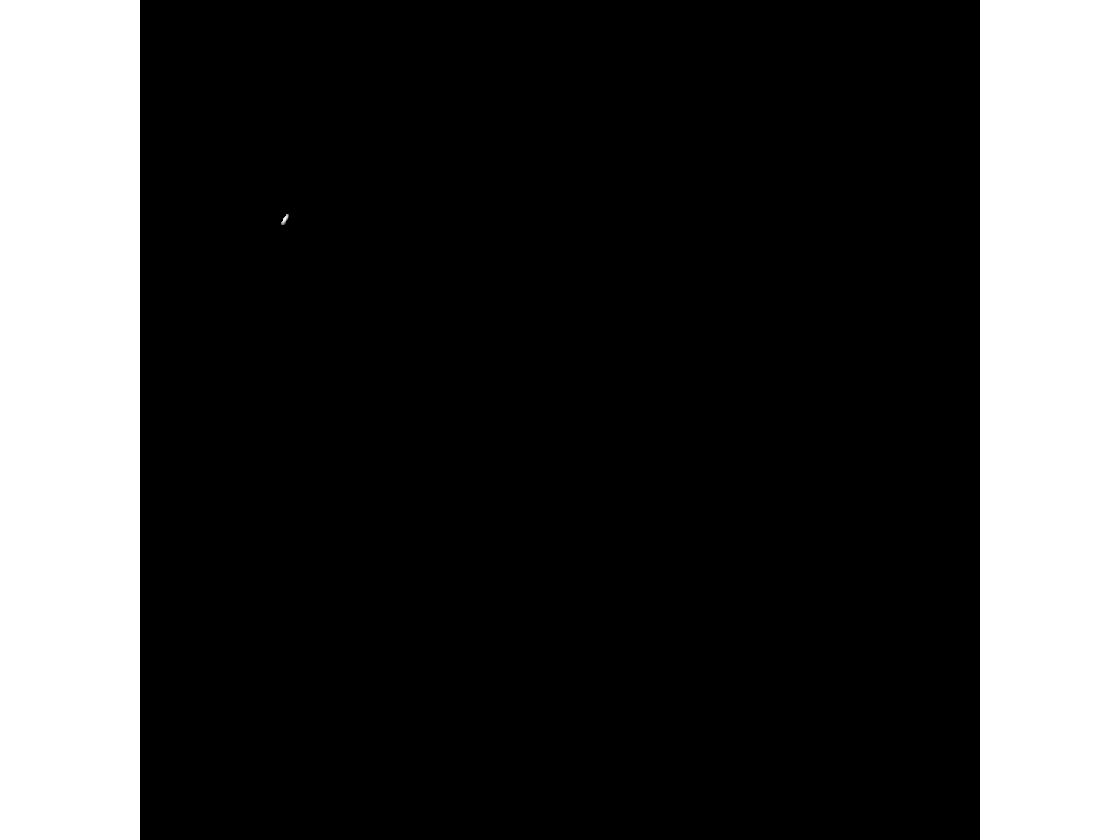

idx = 23; % index of example cell
imshow((imLabel == idx) .* double(imYFP), []) % show the pixel values of the single cell

Let's now loop through each of the objects and perform this operation, saving the fluorescence value every time.

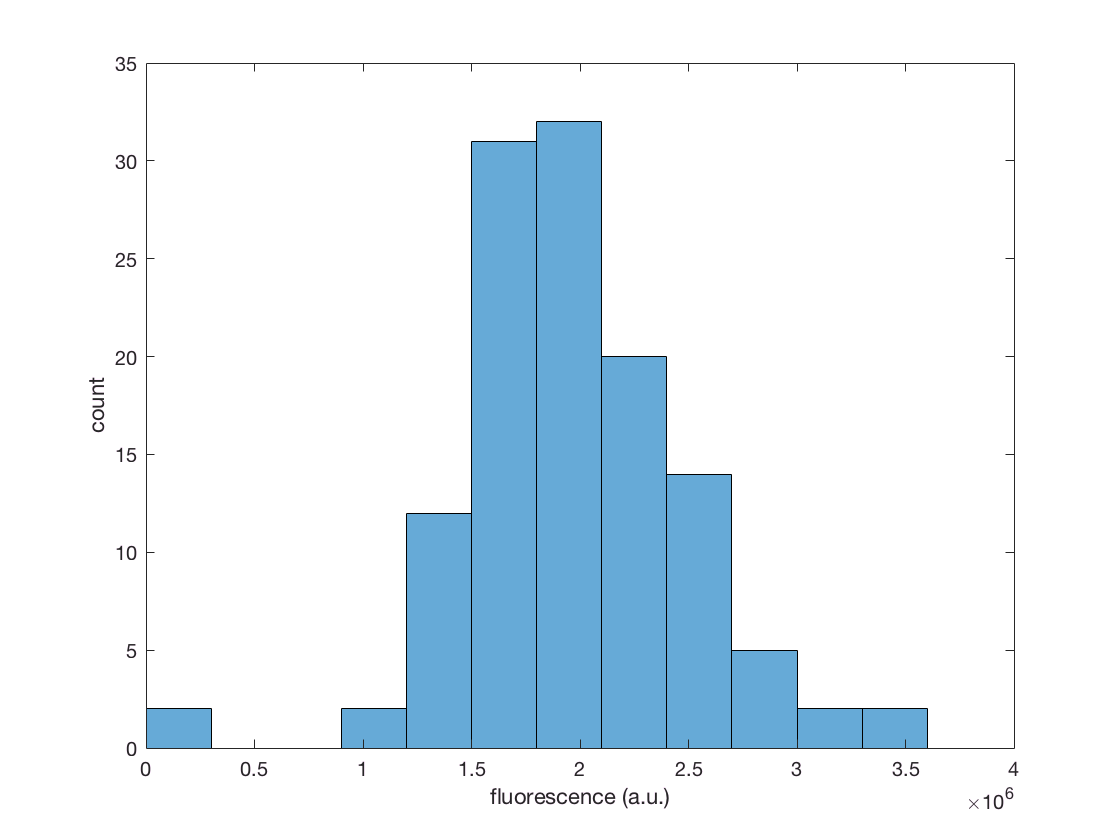

fluor = []; % initialize an empty vector

% loop through each of the objects
for i=1:max(imLabel(:))
    imSingleCell = (imLabel == i) .* double(imYFP); % multiply mask by YFP value
    fluor(i) = sum(imSingleCell(:)); % add all pixel values and save the number
end %for

histogram(fluor)
xlabel('fluorescence (a.u.)')
ylabel('count')

Awesome! Now we have a single-cell distribution of fluorescent values. But this is for a single image. Most of the teams took > 8 images per strain, so we should be able to automate the entire analysis.

The first thing we need to do is find all the directories for each of the strains. For this we will use the `dir `command we use before, then we will use the `.isdir` operation to find which of the listed objects is a directory.

addpath('bfmatlab/');

% define general data directory
% dataDir = 'data/lacI_titration/';
dataDir = '/Volumes/razo_data/MBL/2017/PBoC/20170812_2/';

% Define the area bounds
areaBounds = [2, 3]; %µm^2
% Define the inter-pixel distance
interPix = 0.0733; %µm / pixel

% list all the files inside the lacI_titration directory
dirObjects = dir(dataDir);
% find the directories for each of the strains
dirIdx = [dirObjects.isdir]; % list the index of dir objects
dirObjects = dirObjects(dirIdx); % find the directories
% Loop through each of the directories making sure the length of the name
% makes sense given how we named the files. This is to avoid havin the './' and
% '../' directories listed
strainDirs = {}; % initialize empty cell to save directory names
for i=1:length(dirObjects)
    if length(dirObjects(i).name) > 2
        strainDirs{end+1} = dirObjects(i).name;
    end %if
end %for

Now that we listed the directories we will loop through each of them to then loop through eac of the images contained inside each directory, performing the complete analysis on each data set. Each directory might contain different number of images and different number of cells, therefore we cannot save the results in a regular 2D array with each row being a different directory and each column an individual cell fluorescence value. Instead we will save the single cell measurements using a cell-array.

% initialize cell array to save single cell fluorescence values
fluorValues = {};

% parpool(4)
% Loop through each of the directories
parfor d=1:length(strainDirs)
    strainDirs{d}
    % List all nd2 files inside the directory
    files = dir([dataDir, strainDirs{d}, '/*nd2']);
    % Initialize array to save fluorescent values
    fluor = [];
    % Loop through each of the listed images, performing the complete analysis
    for i=1:length(files)
        % List complete file path
        filePath = [files(i).folder, '/', files(i).name];
        % Generate segmentation mask
        [imLabel, areas, imYFP] = segmenterAreaFilt(filePath, 70,...
                                      areaBounds, interPix);
        % Loop through each object and extract YFP intensity value
        for i=1:max(imLabel(:))
            imSingleCell = (imLabel == i) .* double(imYFP); % multiply mask by YFP value
            fluor(end+1) = sum(imSingleCell(:)); % add all pixel values and save the number
        end %for3 
    end %for2
    fluorValues{d} = fluor;
end %for1


ans =

R60

Reading series #1

ans =

R260

Reading series #1

ans =

R22

Reading series #1

ans =

R124

Reading series #1
    ...
Reading series #1
    ...
    ...
    ...
    ...
Reading series #1
Reading series #1
Reading series #1
Reading series #1
    ...
Reading series #1
    ...
Reading series #1
    ...
    ...
Reading series #1
Reading series #1
    ...
    ...
    ...
Reading series #1
Reading series #1
Reading series #1
    ...
    ...
Reading series #1
Reading series #1
    ...
    ...
Reading series #1
Reading series #1
    ...
    ...

ans =

R1740

Reading series #1
Reading series #1
    ...
    ...
Reading series #1
Reading series #1
    ...
Reading series #1
    ...
Reading series #1
    ...
Reading series #1
    ...
Reading series #1
    ...
Reading series #1
    ...
Reading series #1
    ...
    ...
Reading series #1
Reading series #1
    ...
Reading series #1
    ...

ans =

R1220

Reading series #1
    ...
Reading series #1
    ...
    ...
Reading series #1
Read

save([dataDir,'single_cell_fluorescence.mat'], 'fluorValues')

Having porcessed all of the images, let's take a look of all of the ECDFs

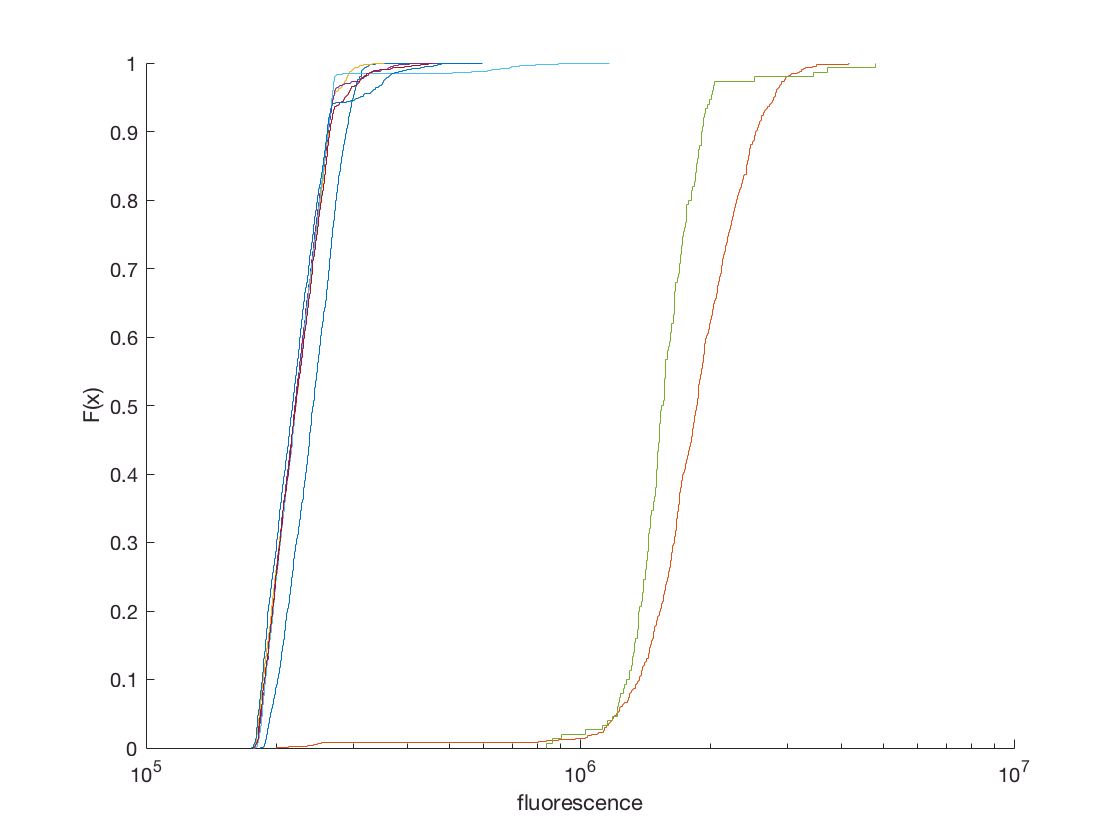

figure()
hold on
for i=1:length(fluorValues)
    ecdf(fluorValues{i})
end %for
xlabel('fluorescence')
set(gca, 'xscale', 'log')
hold off